## Mesh Analysis

Simple linear circuits can be analyzed using Kirchhoff's circuit laws. Matrices provide a natural framework: they can concisely capture the many linear equations that model the circuit network. In this section, you will derive the matrix form of the linear equations that represent a linear circuit and solve for the currents in that circuit using Kirchhoff's voltage law.

**Kirchhoff's voltage law (KVL)**

The sum of voltages around a closed-loop of a circuit is zero. Mathematically:


$$\sum_{k} V_k = 0$$


where $V_k$ is the potential difference across the $k^{th}$ branch of the circuit. Applying Ohm's law gives the potential drop across each resistor: $V = IR$.

 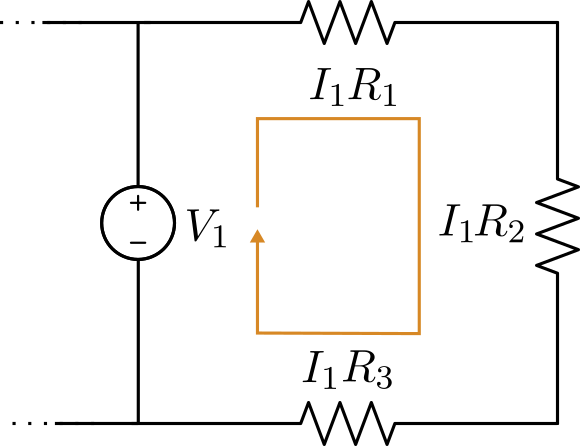

*The potential drop across the resistors in this closed loop must equal the potential generated by the voltage source: *$V_1 - I_1 R_1 - I_1 R_2 - I_1 R_3 = 0$

**Mesh analysis steps.**

- Decide which loops to use and assign each a current variable.

- Write the loop equations by applying KVL.

- Set up the matrix equation. 

- Solve the matrix equation for the currents.

**Example. **Define a matrix equation that solves for the currents in the following linear circuit with

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 20 \ \Omega
\\
R_3 = 15 \ \Omega
\\
R_4 = 2 \ \Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 6 \ \text{V}
\end{array}$$


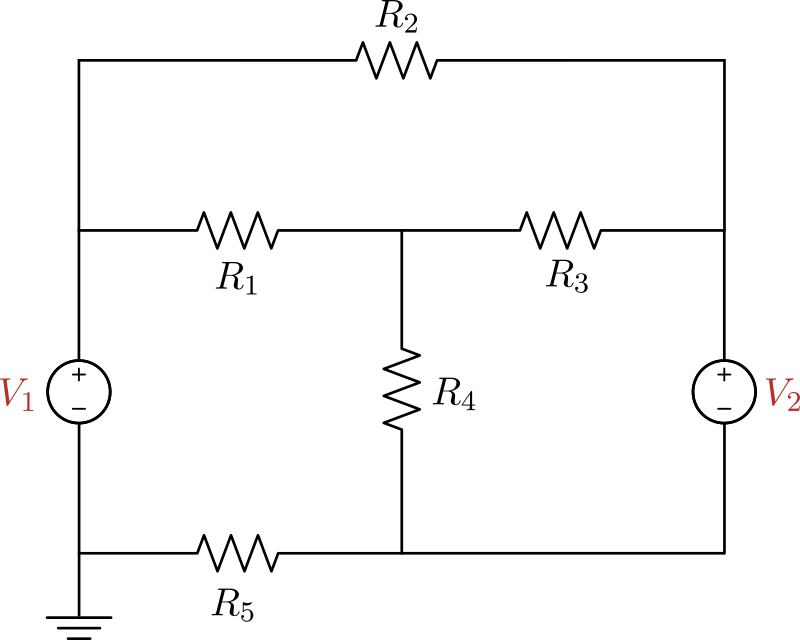

*Circuit diagram*

**Step 1.** **Define the loops**

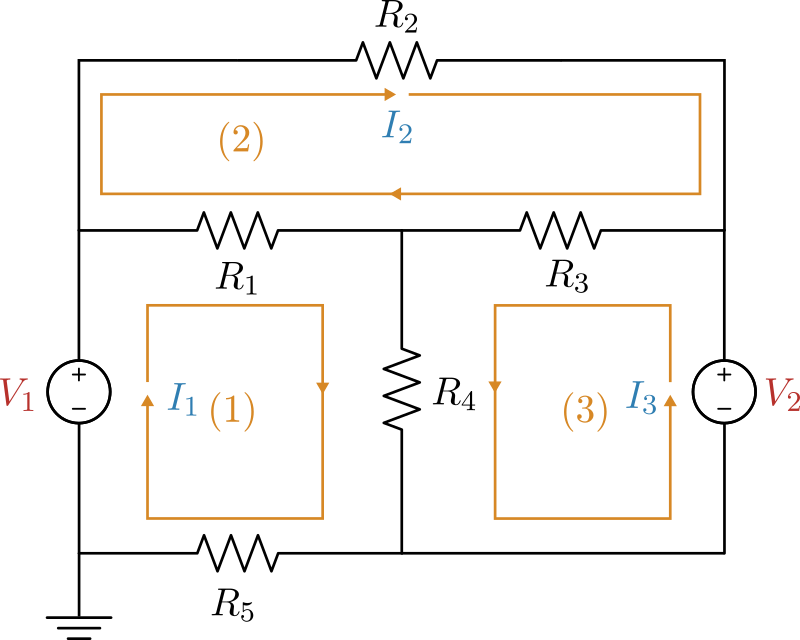

The current through each loop is assigned a variable. In locations where the loops overlap, the current through the branch is taken as a sum or difference of the current variables, depending on the direction.

**Step 2. Write the loop equations**

**Loop (1).** The first loop has four terms; one for each circuit element. By Kirchhoff's voltage law, the sum of voltages around the closed loop must be zero.


$$-V_1 + R_1(I_1 -I_2) + R_4( I_1 + I_3) + R_5 I_1 = 0$$


$I_1$ and $I_2$ were defined in opposing directions, so their diffence is taken. $I_1$ and $I_3$, on the other hand, both travel in the same direction through $R_4$, so their sum is used.

**Loop (2). **The second loop has three terms.


$$R_1(I_2 - I_1) + R_2 I_2 + R_3(I_2 + I_3) = 0$$


**Loop (3). **The third loop also has three terms.


$$-V_2 + R_3(I_2 + I_3) + R_4(I_3 + I_1) = 0$$


**Step 3. Set up the matrix equation**. 

Before setting up the matrix equation, rewrite the equations in terms of the unknown $I_i$'s and move the constant terms to the right-hand side.


$$-V_1 + R_1(I_1 -I_2) + R_4( I_1 + I_3) + R_5 I_1 = 0$$
   
$$\rightarrow$$
   
$$(R_1 + R_4 + R_5) I_1 - R_1 I_2 + R_4 I_3 = V_1$$



$$R_1(I_2 - I_1) + R_2 I_2 + R_3(I_2 + I_3) = 0$$
              
$$\rightarrow$$
    
$$-R_1 I_1 + (R_1 + R_2 + R_3) I_2 + R_3 I_3 = 0$$



$$-V_2 + R_3(I_2 + I_3) + R_4(I_3 + I_1) = 0$$
              
$$\rightarrow$$
    
$$R_4 I_1 + R_3 I_2 + (R_3 + R_4) I_3 = V_2$$


The matrix equation is created by defining the variable of unknown currents

    
$$\mathbf{I} = \left[ \begin{array}{l} I_1 \\ I_2 \\ I_3 \end{array} \right]$$


Then, the system is converted into matrix notation $\mathbf{A} \mathbf{I} = \mathbf{b}$, using the coefficients of the unknown $I_i$'s to build the coefficient matrix.

    
$$\left( \begin{array}{rl}  
R_1 + R_4 + R_5  & -R_1 & R_4\\
-R_1 & R_1 + R_2 + R_3 & R_3 \\
R_4 & R_3 & R_3 + R_4 \\
\end{array} \right)
\left( \begin{array}{l} I_1 \\ I_2 \\ I_3 \end{array} \right)
=
\left( \begin{array}{l} V_1 \\ 0 \\ V_2 \end{array} \right)$$


**Step 4. Solve the matrix equation in MATLAB.**

To solve the matrix system in MATLAB, start by defining the values of the resistors and voltage sources. Recall that


$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 20 \ \Omega
\\
R_3 = 15 \ \Omega
\\
R_4 = 2 \ \Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 6 \ \text{V}
\end{array}$$


R1 = 10;
R2 = 20;
R3 = 15;
R4 = 2;
R5 = 330;
V1 = 1.5;
V2 = 6;

Next, define the coefficient matrix $\mathbf{A}$ and constant vector $\mathbf{b}$.

A = [R1+R4+R5,      -R1,     R4; 
          -R1, R1+R2+R3,     R3;
           R4,       R3,  R3+R4];
b = [V1; 0; V2]

b =     1.5000
         0
    6.0000


Then, solve the matrix system with the backslash (`\`) operator. To solve $\mathbf{A} \mathbf{I} = \mathbf{b}$, use

I = A\b

I =    -0.0035
   -0.1679
    0.5015


**Validating the result in Simscape.**

You can check your result by creating a model of the electrical circuit in Simscape and then looking at the variable values. For this example, a model of the circuit has already been created.

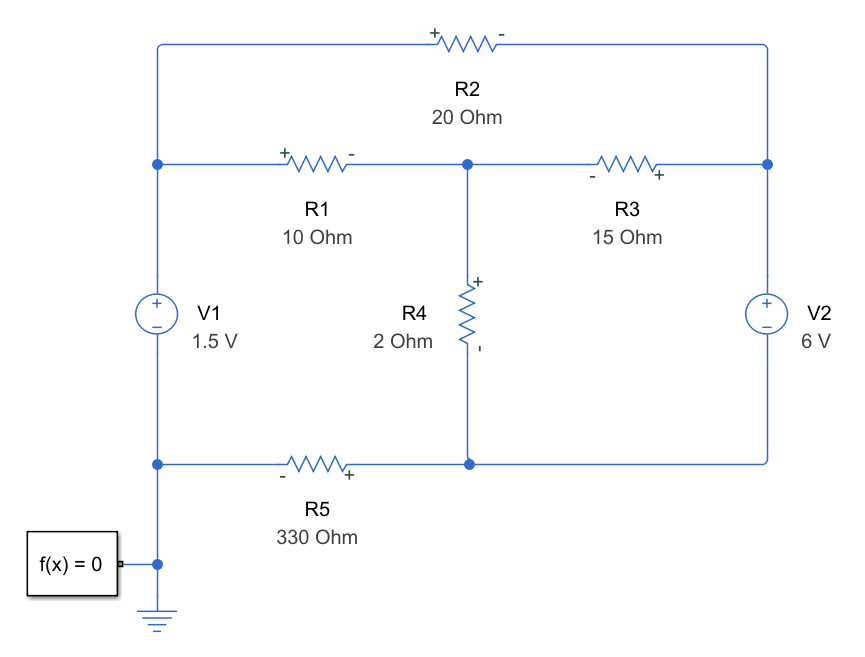

*Simscape model of the circuit.*

To use the model, you only need to complete three steps.

1. Open the model [circuitExample.slx](matlab: circuitExample) (note that the model must be on the MATLAB Search Path for the link to work) and click **Run** in the **Simulation** tab.

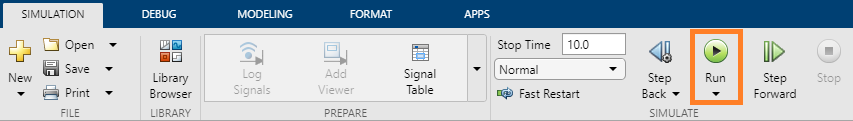

2. In the **Debug** tab, click on the **Simscape **tab and then select **Variable Viewer**.

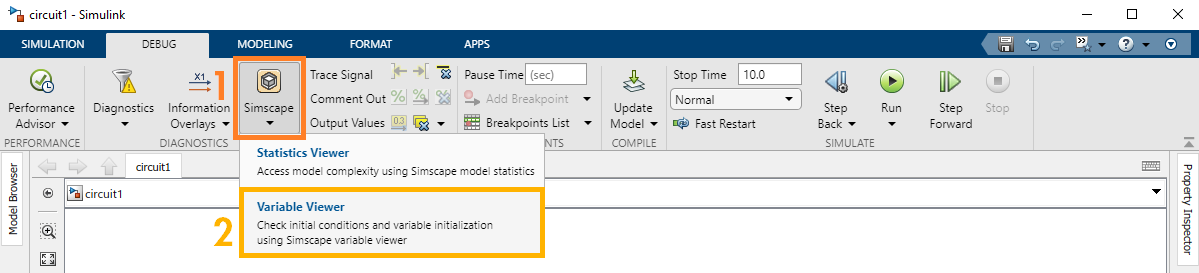

3. Inside the variable viewer, find the relevant circuit element, and examine the current variable `i`. In MATLAB, we computed `I2 = -0.1679`. The current $I_2$ passes through $R_2$. The variable viewer shows that the current through $R_2$ matches the result computed in MATLAB.